We want to explore if there is a way (and how accurate it would be) to detect changes in a given video stream (i.e changes from frame to frame) while only working with a proportion of the pixels.

We are going to try one main method where we are going to use edge detection to figure out where the main areas of the image is. We will then figure out what mean value all the pixels in the areas have. These values will then be compared from frame to frame too see if they differ dramatically (this threshold will be a parameter whose value needs to be set carefully). If there is a different amount of areas from frame to frame this also signals a change. This method will then be compared to a baseline where we just consider a random subset of pixels and the values of these and how these differ. 

% What proportion of the pixels?
% Why not just send a low-res image?
% Segmentation?

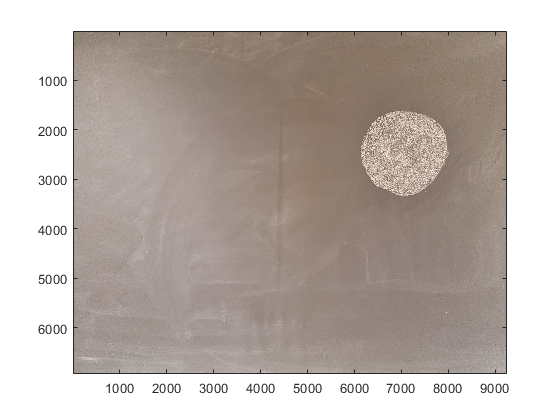

%*- Read 'Image 1', convert to binary image and show.
I1 = imread('blackboard_images/first.jpg');
image(I1);

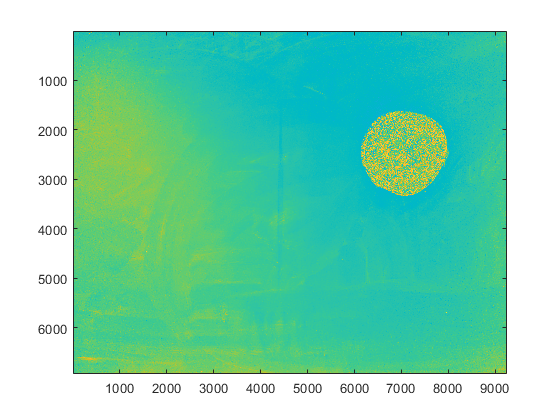

% I1_bw = imbinarize(I1);
I1_bw = rgb2gray(I1);
image(I1_bw);

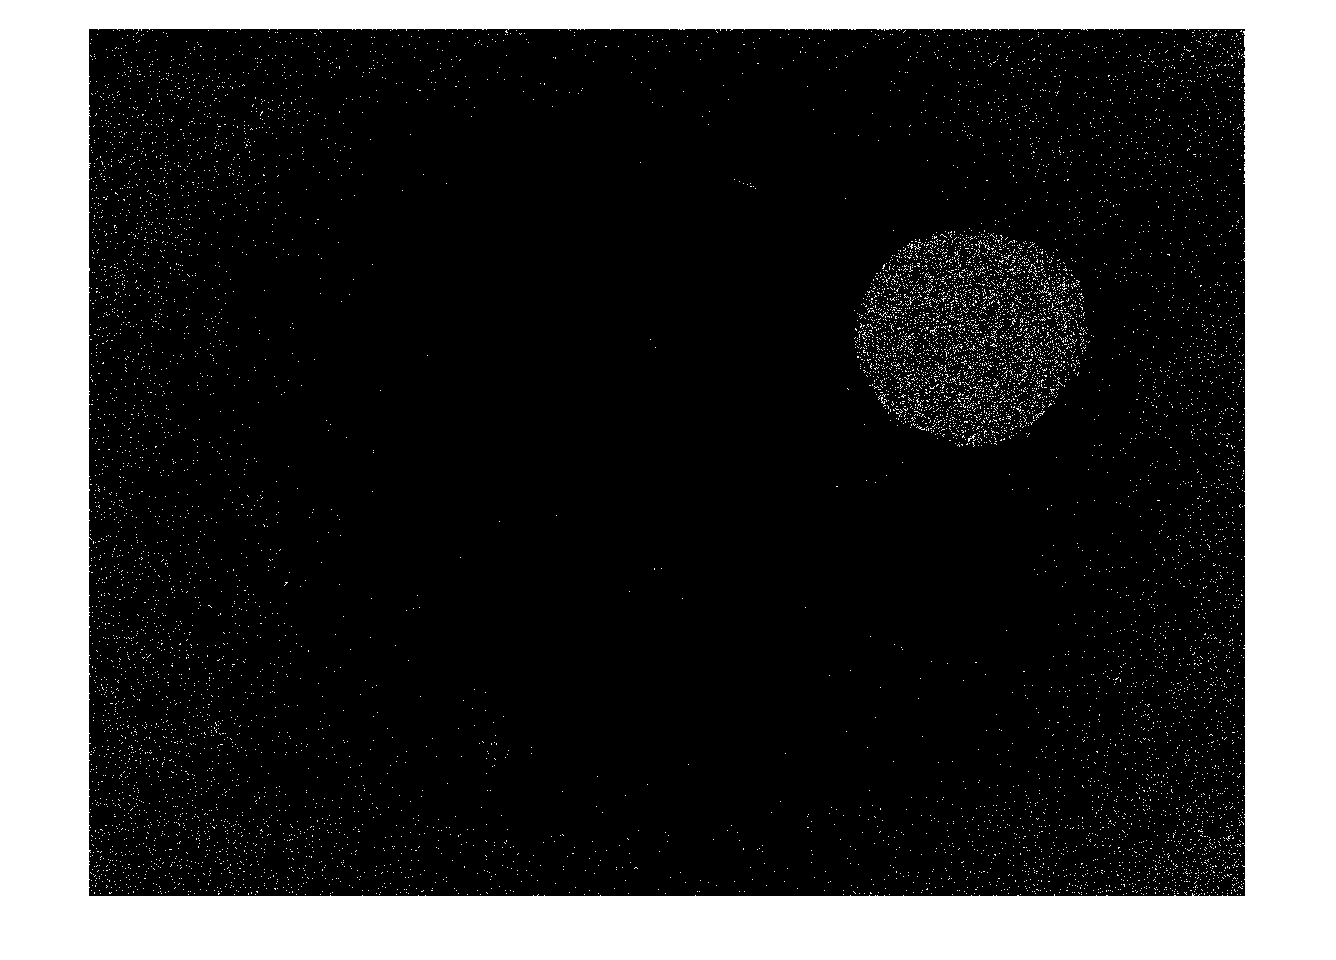

BW1 = edge(I1_bw,'Canny', 0.2);
BW2 = edge(I1_bw,'Prewitt');
imshow(BW2);


% Go on to find connected components of the image and then
% extract the pixel values from there and find the mean and such.

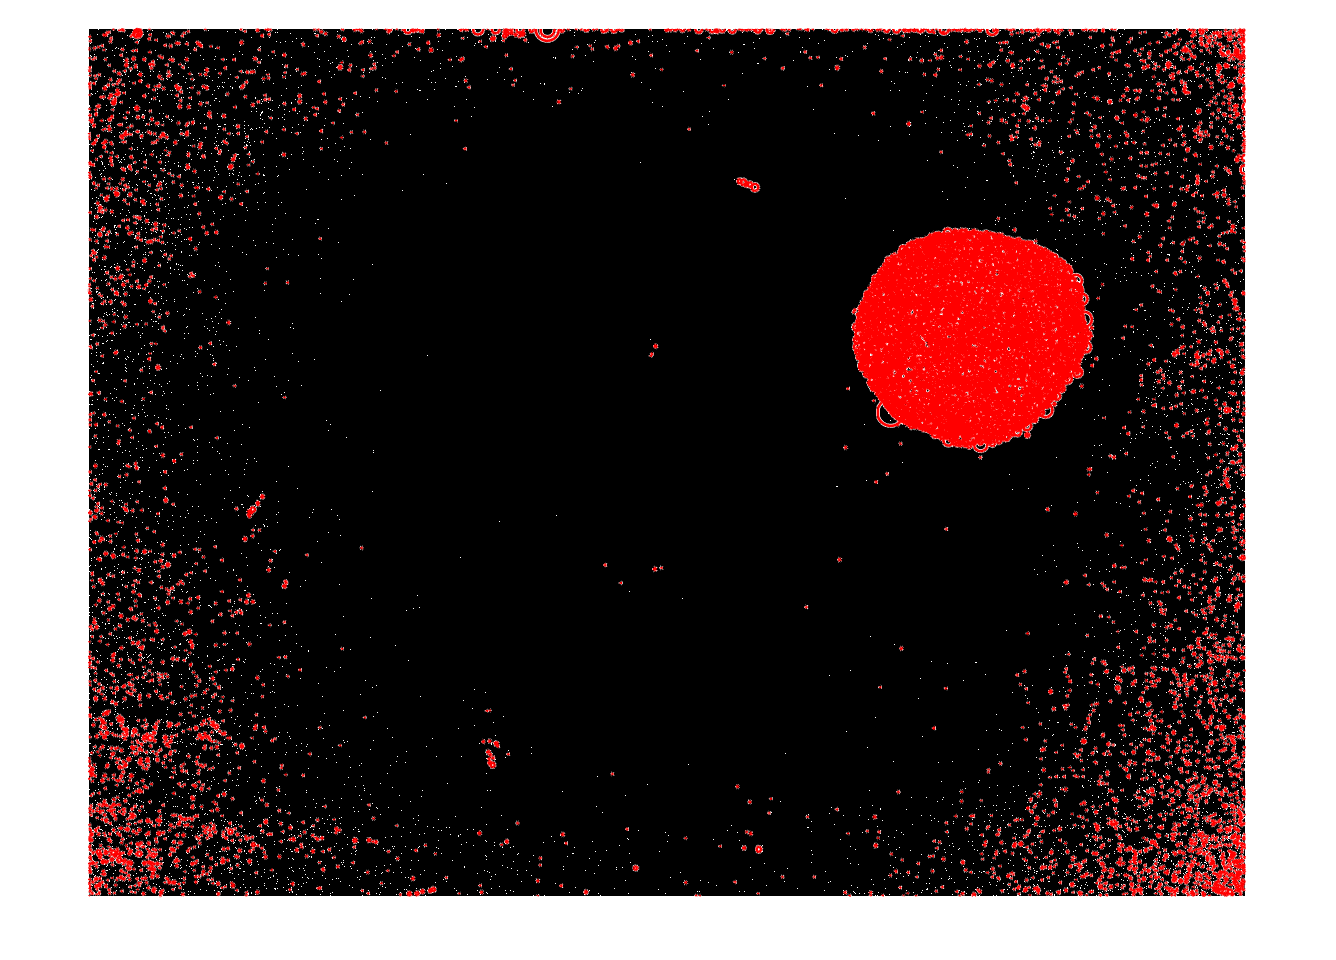

stats = regionprops('table',BW1,'Centroid',...
    'MajorAxisLength','MinorAxisLength');

centers = stats.Centroid;
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;

hold on
viscircles(centers,radii);
hold off

CC = bwconncomp(BW1)

CC = struct with fields:
    Connectivity: 8
       ImageSize: [6936 9248]
      NumObjects: 14944
    PixelIdxList: {1×14944 cell}


%I2 = imread('blackboard_images/second.jpg');
%image(I2);

%I3 = imread('blackboard_images/third.jpg');
%image(I3);

%I4 = imread('blackboard_images/fourth.jpg');
%image(I4);

%I5 = imread('blackboard_images/fifth.jpg');
%image(I5);